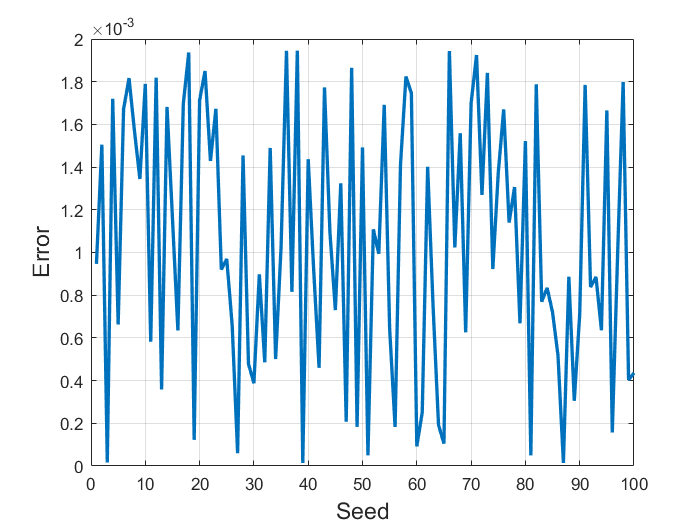

clc;
clear;

dt_double = 'double';
dt_single = 'single';
dt_FxPt   = 'FxPt';

T = FFT_8_Point_Radix_2_types(dt_FxPt,8);

%Design parameters
NumOfInputSamples_N = 8;
nSeeds = 100;
error = zeros(1,nSeeds);

% Preallocate storage for fi objects
All_Inputs  = fi(zeros(nSeeds, NumOfInputSamples_N), T.FFT_Algo_In.numerictype); 
All_Outputs_real = fi(zeros(nSeeds, NumOfInputSamples_N), T.FFT_Algo_Out.numerictype);
All_Outputs_img  = fi(zeros(nSeeds, NumOfInputSamples_N), T.FFT_Algo_Out.numerictype);

for seed = 1 : nSeeds
    rng(seed);
    
    %Create test inputs
    FFT_Golden_In = rand(1, NumOfInputSamples_N);   % 1x8 row
    FFT_Algo_In = cast(FFT_Golden_In, 'like', T.FFT_Algo_In);
    
    %FFT 8-Point Radix-2 algorithm
    FFT_Algo_Out = FFT_8_Point_Radix_2_mex(FFT_Algo_In, T);
    
    %Verify result
    FFT_Golden_Out = fft(FFT_Golden_In);
    error(seed) = abs(mean(double(FFT_Algo_Out) - FFT_Golden_Out));
    
    % Save this seed’s input/output into storage
    All_Inputs(seed,:) = FFT_Golden_In;
    All_Outputs_real(seed,:) = real(FFT_Golden_Out);
    All_Outputs_img(seed,:) = imag(FFT_Golden_Out);
end

%Plot
figure;
plot(1:nSeeds, error, 'LineWidth', 2);
grid on;
xlabel('Seed', 'FontSize', 14);
ylabel('Error', 'FontSize', 14);


% Write *all* seeds to external files
% writematrix(All_Inputs.bin,  'FFT_Golden_In.txt',  'Delimiter','\t');
% writematrix(All_Outputs_real.bin, 'FFT_Golden_Out_real.txt', 'Delimiter','\t');
% writematrix(All_Outputs_img.bin, 'FFT_Golden_Out_img.txt', 'Delimiter','\t');

% === Write fixed-point binary representation ===
fid = fopen('FFT_Golden_In_bin.txt','w');
for k = 1:numel(All_Inputs)
    fprintf(fid, '%s\n', bin(All_Inputs(k)));
end
fclose(fid);

fid = fopen('FFT_Golden_Out_real_bin.txt','w');
for k = 1:numel(All_Outputs_real)
    fprintf(fid, '%s\n', bin(All_Outputs_real(k)));
end
fclose(fid);

fid = fopen('FFT_Golden_Out_img_bin.txt','w');
for k = 1:numel(All_Outputs_img)
    fprintf(fid, '%s\n', bin(All_Outputs_img(k)));
end
fclose(fid);

showInstrumentationResults FFT_8_Point_Radix_2_mex -proposeFL -defaultDT numerictype(1,32)